## **ME: 6240 Long Homework #1**

Static Parameter Estimation

Michael Swafford

The goal for this long homework is to explore some aspects of static parameter estimation techniques, both with handwritten examples and coded examples.

First, we are going to explore the tradeoff between bias and variance that exists for most estimators.

# 1) Show how the measn squared error (MSE) for an estimator can be decomposed into bias and variance terms for the case of a vector parameter.

$x$** will be our vector parameter of interest. The MSE is defined as:**

### 
$$MSE = \frac{1}{n}\Sigma(\hat x-x)^2$$


**where **$\hat x$** is our vector of observed measurements of our parameter and **$x$** is the true vector of our parameter.**

- **rewrite MSE as an expectation**

### 
$$MSE = \frac{1}{n}\Sigma(\hat x-x)^2 = E_x [(\hat x -x)^2]$$


         **2. Add and subtract the expectation of **$\hat x$ **inside the parentheses**

### 
$$= E_x[((\hat x-E_x[\hat x])+(E_x[\hat x]-x))^2]$$


         **3. Expand the expression, keying in on the groupings shown above**  

### 
$$=E_x[(\hat x - E_x[\hat x])^2+2(\hat x -E_x[\hat x])(E_x[\hat x]-x)+(E_x[\hat x]-x)^2]$$


**         4. Distribute **$E_x$

### 
$$=E_x[(\hat x - E_x[\hat x])^2]+E_x[2(\hat x -E_x[\hat x])(E_x[\hat x]-x)]+E_x[(E_x[\hat x]-x)^2]$$


**         5. Substitue definitions for **$var(x)=E_x[(\hat x -E_x[\hat x])^2]$ and $bias(x) = E_x[\hat x] - x$

### 
$$=var(x)+E_x[2(\hat x -E_x[\hat x])(bias(x))]+E_x[(bais(x))^2]$$
 

         **6. Use the fact that the expectation of a bias is the bias**

### 
$$=var(x)+2(E_x[(\hat x -E_x[\hat x])]bias(x))+(bais(x))^2$$


**         7. Distribute **$E_x$ **and the fact that the expectation of an expectation is the original expectation**

### 
$$=var(x)+2((E_x[\hat x] -E_x[\hat x])bias(x))+(bais(x))^2$$


### 
$$=var(x)+2((0)bias(x))+(bais(x))^2$$


### 
$$=var(x)+(bais(x))^2$$


# 2) Let's assume we have a vector with *N* elements, $x = [x_1,...x_N]^T$, where each $x_i$ element is independent and identically distributed (iid) according to a normal distribution, i.e., $x\sim \mathcal{N}(\mu,\,\sigma^2)$. Consider the following two estimators for variance. 

# 
$$\hat \sigma^2 = \frac{1}{N}\Sigma(x_i - \overline x)^2$$


# 
$$S^2 = \frac{1}{N-1}\Sigma(x_i - \overline x)^2$$


# Where the first is a "population" variance and the second is a "sample" variance. **Determine the bias and variance of each estimator.**

# **Which estimator has a smaller MSE?**

To answer this question, it may be useful to consider the ratio of the MSEs from each estimator. 

Hint: You can calculate the bias and variance directly, or you could make use of the chi-squared dsitrubution: $\frac{1}{\sigma^2}\Sigma(x_i-\overline x)^2 \sim X^2_{N-1}$

- Bias for population variance estimator

### 
$$bais(\hat\sigma^2)=E[E[(x_i-\overline x)^2]]-\hat\sigma^2 = E[(x_i-\overline x)^2] - \hat\sigma^2$$


### 
$$=E[\frac{1}{n}\Sigma((x_i-E[x])-(\overline x -E[x]))^2]-\hat\sigma^2$$


### 
$$=E[\frac{1}{n}\Sigma((x_i-E[x])^2-2(\overline x -E[x])(x_i-E[x])+(\overline x -E[x])^2)]-\hat\sigma^2$$


### 
$$=E[\frac{1}{n}(\Sigma(x_i-E[x])^2-2(\overline x -E[x])\Sigma(x_i-E[x])+(\overline x -E[x])^2\Sigma1)]-\hat\sigma^2$$


### 
$$=E[\frac{1}{n}\Sigma(x_i-E[x])^2-\frac{2}{n}(\overline x-E[x])\Sigma(x_i-E[x])+(\overline x-E[x])^2]-\hat\sigma^2$$


### 
$$\overline x -E[x] = \frac{1}{n}\Sigma(x_i-E[x])$$


### 
$$=E[\frac{1}{n}\Sigma(x_i-E[x])^2-2(\overline x-E[x])^2+(\overline x-E[x])^2]-\hat\sigma^2$$


### 
$$=E[\frac{1}{n}\Sigma(x_i-E[x])^2]-E[(\overline x-E[x])^2]-\hat\sigma^2$$


### 
$$=\hat\sigma^2-E[(\overline x-E[x])^2]-\hat\sigma^2$$


### 
$$=(1-\frac{1}{n})\hat\sigma^2-\hat\sigma^2$$


- Variance for population variance estimator

### 
$$var(\hat\sigma^2) = E[(\hat\sigma^2-E[\hat\sigma^2])^2]$$


### 
$$=E[(\hat\sigma^2-E[E[(x_i-\overline x)^2]])^2]$$


### 
$$=E[(\hat\sigma^2-(1-\frac{1}{n})\hat\sigma^2)^2]$$


### 
$$=E[(\frac{1}{n}\hat\sigma^2)^2]$$


### 
$$=\frac{1}{n^2}E[\hat\sigma^4]$$


### 
$$=\frac{1}{n^2}3\hat\sigma^4$$


- Bias for sample variance estimator

### 
$$bias(S^2)=E[S^2]-\hat\sigma^2 = E[\frac{1}{n-1}\Sigma(x_i-\overline x)^2]-\hat\sigma^2$$


### 
$$\frac{n}{n-1}E[\frac{1}{n}\Sigma(x_i-\overline x)^2]-\hat\sigma^2$$


### 
$$=\frac{n}{n-1}(1-\frac{1}{n})\hat\sigma^2-\hat\sigma^2$$


### $=0$ (unbiased)

- Variance for sample variance estimator

### 
$$var(S^2) = E[(S^2-E[S^2])^2]$$


### 
$$=E[( S^2-E[\frac{1}{n-1}\Sigma(x_i-\overline x)^2])^2]$$


### 
$$=E[(S^2-(\frac{n}{n-1})(1-\frac{1}{n})\hat\sigma^2)^2]$$


### 
$$=E[(S^2-\hat\sigma^2)^2] $$


### 
$$=E[S^4]-2E[S^2]E[\hat\sigma^2]+E[\hat\sigma^4]$$


### 
$$=3\hat\sigma^4-2(\hat\sigma^2)(1-\frac{1}{n})\hat\sigma^2+3\hat\sigma^4$$


### 
$$=2\hat\sigma^4(2+\frac{1}{n})$$


### Comparing the MSE's

- MSE population variacne:

### 
$$MSE(\hat\sigma^2)=bias(\hat\sigma^2)^2+var(\hat\sigma^2)$$


### 
$$\frac{1}{n^2}\hat\sigma^4+\frac{1}{n^2}(1-\frac{1}{n})^2\hat\sigma^4$$


### 
$$\frac{1}{n^2}(1+(1-\frac{1}{n})^2)\hat\sigma^4$$


- MSE sample variance:

### 
$$MSE(S^2)=bias(S^2)^2+var(S^2)$$


### 
$$=0 +\hat\sigma^4-2\hat\sigma^4(1-\frac{1}{n})+\frac{1}{n^2}(1-\frac{1}{n})^2\hat\sigma^4$$


### 
$$=\hat\sigma^4(1-2(1-\frac{1}{n})+\frac{1}{n^2}(1-\frac{1}{n})^2)$$


### By inspection we can see that the population variacne is divided by a factor of $n^2$ **which will result in a significantly smaller MSE than the sample variance.**

# (Problems 3-5) **MMSE estimation with correlated noise. **Given the prior information $x \sim \mathcal{N}(\overline x,\sigma^2_0)$and the measurements.

# 
$$z(j) = x+w(j)$$
        
$$j=1,2$$


# With the jointly Gaussian measurement noises $w(j)\sim\mathcal{N}(0,\sigma^2)$independent of $x$ but correlated among themselve, with

# 
$$E[w(1)w(2)]=\rho\sigma^2$$


# 3) Find the variance of the MMSE estimator of x conditioned on these measurements.

hint: equation 3.2.1-8 will be handy

### $P_{xx|z} = P_{xx}-P_{xz}P^{-1}_{zz}P_{zx}$            eqn 3.2.1-8

### 
$$P_{xx} = \sigma_0^2$$


### 
$$P_{xz} =\pmatrix {\sigma_0^2 & \sigma_0^2}$$


### 
$$P_{zz} = E[(z-\overline z)(z-\overline z)^T]$$


### 
$$P_{zz} = E[(x+w-\overline z)(x+w-\overline z)^T]$$


### 
$$P_{zz} = E[xx^T+xw^T-x\overline z^T+wx^T+ww^T-w\overline z^T-\overline zx^T-\overline zw^T+\overline z \overline z^T]$$


### 
$$P_{zz} = E[xx^T]+0-E[x\overline z^T]+0+E[ww^T]-0-E[\overline zx^T]-0+E[\overline z \overline z^T]$$


### 
$$P_{zz} = E[xx^T]-\overline x\overline x^T+\rho\sigma^2-\overline x\overline x^T+\overline x\overline x^T$$


### 
$$P_{zz} = \sigma_0^2+\rho\sigma^2=\pmatrix{\sigma_0^2+\sigma^2  & \sigma_0^2+\rho\sigma^2 \cr
 \sigma_0^2+\rho\sigma^2 &  \sigma_0^2+\sigma^2}$$


### 
$$P_{xx|z} = \sigma_0^2-\pmatrix {\sigma_0^2 & \sigma_0^2}*\pmatrix{\sigma_0^2+\sigma^2  & \sigma_0^2+\rho\sigma^2 \cr
 \sigma_0^2+\rho\sigma^2 &  \sigma_0^2+\sigma^2}^{-1}*\pmatrix {\sigma_0^2 \cr \sigma_0^2}$$


### 
$$=\sigma_0^2 -\frac{2\sigma_0^2(\sigma_0^2(-\sigma_0^2-\sigma^2)+\sigma_0^2(\sigma_0^2+\rho\sigma^2))}{(\rho-1)\sigma^2(2\sigma_0^2+(\rho+1)\sigma^2))}$$


### 
$$=\frac{\sigma_0^2\sigma^2(1+\rho)}{2\sigma_0^2+\sigma^2(1+\rho)}$$


# 4) If $\overline x =10, \sigma_0=1,$ and $\rho = 0.5,$ how accurate should the measurements be (ie find$\sigma$) if we want the estimate to be within 10% of the true value with 99% probability?

hint: the example in section 2.6.3 could provide valuable insight for how to tacke this problem 

### 
$$\overline x \pm z*\frac{\sigma}{\sqrt{n}}=0.99$$


### 
$$\overline x*0.10=2.576*\frac{\sigma}{\sqrt{n}}$$


### 
$$(\frac{10*0.10*\sqrt{2}}{2.576})^2=\sigma^2 = \frac{\sigma_0^2\sigma^2(1+\rho)}{2\sigma_0^2+\sigma^2(1+\rho)}$$


### 
$$0.301 = \frac{(1)^2\sigma^2(1+0.5)}{2(1)^2+\sigma^2(1+0.5)}$$


### Standard of Deviation $\sigma$ can be no larger than 0.758 for the estimate to be within 10% of the true value with 99% probability.

# 5) Repeat the previous question's calculations if $\rho$= 0. Comment on the difference between the accuracy required for correlated measurements compared to independnt measurements.

### 
$$0.301 = \frac{(1)^2\sigma^2(1+0)}{2(1)^2+\sigma^2(1+0)}$$


### Standard of Deviation $\sigma$ is 0.929 for the estimate to be within 10% of the true value with 99% probability. Uncorrelated measurements do NOT have to be as accurate as correlated since the allowable standard of deviation is larger (~22.5% larger allowable $\sigma$)

## Now, we are going to work with some simulated data and explore the results from a couple types of estimators. Let's assume we have some kind of mechanical system whise design includes a sensor that we need for closed-loop controller. After several trial runs, we determine that we could achieve superior performance if we had a better understanding of the sensor's characteristics. Unfortunately, the data sheet is laughably incomplete; all it provides is the sensor noise ($\sigma=0.02$ units). So, we collect some data to quantify the characteristics we are interested in better understanding, which in this case is sensor bias, *b. *Specifically, that data collection is conducted such that the observations, $z_i$, can be assumed to take the form:

## $z_i=b+w_i$ for $i=1,...,N$

## where the noise is assumed to be Gaussian, $w_i \sim \mathcal{N}(0,\sigma^2),$ and independent of *b *and each other.

load('data.mat')

**The MATLAB data file provided on ICON was loaded into this workspace, and contains a structure called LHW1data that contains 3 substructures and each substructure contains the following three variables:**

- **b: the true value of the bias**

- **N: the number of samples**

- **z: and Nx1 vector of samples**

**The data in substructure q67 is for questions 6 and 7, substructrue q8 is for question 8, and substructure q9 is for question 9.**

# **6) Estimate the bias with a Maximum Likelihood Estimator (**$\hat b_{MLE}$**). Comment on the estimate compared to the true value.**

### 
$$\hat b_{MLE} = argmax_b\Lambda_Z(b)$$


### 
$$ln\Lambda(b) = -\frac{1}{2}ln(2\pi\sigma^2)-\frac{1}{2\sigma^2}(Z-b)^2$$


### 
$$\frac{\partial ln\Lambda(b)}{\partial b} = \frac{1}{\sigma^2}(Z-b)=0$$


### 
$$\hat b_{MLE} = \overline z$$


z6=LHW1data.q67.z;
bmle = mean(z6);
b6true = LHW1data.q67.b;
fprintf('The maximum likelihood estimate of the bias is %f and the true bias is %f',bmle,b6true)

The maximum likelihood estimate of the bias is 0.590350 and the true bias is 0.589077

### The MLE is a decent estimate of the true bias being 0.001273 units away from the true value of the bias and is an overprediction of the true bias.

## After estimating the bias, our controller is doing better than before considering the sensor bias. But as we conduct more and more experiments, we notice that the bias appears to be changing every time we turn on the system. So we turn to the internet and search via Google to see if anyone has investigated the turn-on bias instability for our particular sensor. Lo and behold, some good Samaritan has indeed characterized this for us! They find that turn-on bias instability behaves according to a beta distribution, $b \sim \mathcal{B}e(\alpha=1,\beta=3),$or

## 
$$b \sim \frac{1}{B(\alpha,\beta)}b^{\alpha-1}(1-b)^\beta$$


## Where $B(\alpha,\beta)$is the beta function.

# **7) Estimate the bias with a maximum A Posteriori Estimator (**$\hat b_{MAP}$**). Comment on how the estimate compares to the true value as well as **$\hat b_{MLE}$**.**

### 
$$\hat b_{MAP} = argmax_b[p(Z|b)p(b)]$$


### 
$$p(b) =\frac{1}{B(1,3)}b^{1-1}(1-b)^3$$


### 
$$B(1,3) = \frac{(1-1)!(3-1)!}{(1+3-1)!}=\frac{1*2}{3!}=\frac{1}{3}$$


### 
$$p(b) =3(1-b)^3$$


### 
$$ln(p(Z|b)p(b)) =3ln(1-b)+ln(3) -\frac{1}{2}ln(2\pi\sigma^2)-\frac{1}{2\sigma^2}(Z-b)^2$$


### 
$$ln(p(Z|b)p(b)) =3ln(1-b)+ln(3) -\frac{1}{2}ln(2\pi\sigma^2)-\frac{1}{2\sigma^2}\Sigma(z-b)^2$$


### 
$$ln(p(Z|b)p(b)) =3ln(1-b)+ln(3) -\frac{1}{2}ln(2\pi\sigma^2)-\frac{1}{2\sigma^2}\Sigma z^2+\frac{b}{\sigma^2}\Sigma z-\frac{b^2N}{2\sigma^2}$$


### 
$$\frac{\partial ln(p(Z|b)p(b))}{\partial b} =\frac{3}{1-b}+0-0-0+\frac{1}{\sigma^2}\Sigma z-\frac {bN}{\sigma^2}=0$$


### 
$$\frac{3}{1-b}+\frac{\overline zN}{\sigma^2}-\frac {bN}{\sigma^2}=0$$


### 
$$\hat b_{MAP}= \frac{-\sqrt{\overline z^2N-2\overline zN+N-12\sigma^2}+\overline z\sqrt{N}+\sqrt{N}}{2\sqrt{N}}$$


sigma7 = 0.02;
z7bar = mean(z6);
N7 = LHW1data.q67.N;
num7 = -sqrt(z7bar^2*N7-2*z7bar*N7+N7-12*sigma7^2)+z7bar*sqrt(N7)+sqrt(N7);
denom7 = 2*sqrt(N7);
bmap = num7/denom7;
b6true;
fprintf('The maximum A Priori estimate of the bias is %f, and the true bias is %f',bmap,b6true)

The maximum A Priori estimate of the bias is 0.591820, and the true bias is 0.589077

### MAP is within 0.002743 of the true value and is an overprediction. The MAP has a noticebly larger error from the true value than the MLE by 115% more than the MLE. 

# 8) Repeat the calculations for 6 and 7 with the larger dataset. Comment on how the estimates compare to the true value as well as to each other

zBar = mean(LHW1data.q8.z);
N8 = LHW1data.q8.N;
bMle = zBar;
sigma8 = 0.02;
%sigma8 = std(LHW1data.q8.z)
num8 = -sqrt(zBar^2*N8-2*zBar*N8+N8-12*sigma8^2)+zBar*sqrt(N8)+sqrt(N8);
denom8 = 2*sqrt(N8);
bMap = num8/denom8;
b8True = LHW1data.q8.b;
fprintf('The maximum likelihood estimate of the bias is %f, the MAP of the bias is %f, and the true bias is %f',bMle,bMap,b8True)

The maximum likelihood estimate of the bias is 0.026213, the MAP of the bias is 0.026213, and the true bias is 0.026189

### Both the MLE and the MAP get to the same value estimate for the bias of 0.026213, this is within 2.4E-5 of the true bias value. Both are a slight overprediction of the true bias value. 

## Now we are going to consider the similarities and differences between MLE, LSE, and BLUE. It turns out that these three estimators are equivalent when the following assumptions hold:

- The model describing the relationship between the parameter(s) and the obersvations is linear

- The variance in the noise does not change

- The noise is normally distributed

- The noise is uncorrelated

## Let's say we make all of these assumptions, but it turns out the noise should actually be modeled as a random walk (the variance grows linearly with time). For this problem, we are going to assume that the sensor noise is $\sigma=0.075$units. We will also assume that the sampling rate for the sensor is 100 Hz and that time starts at t=1.

# 9) Estimate the bias with MLE, LSE, and BLUE. Comment on how the estimates compare to the true value as well as to each other.

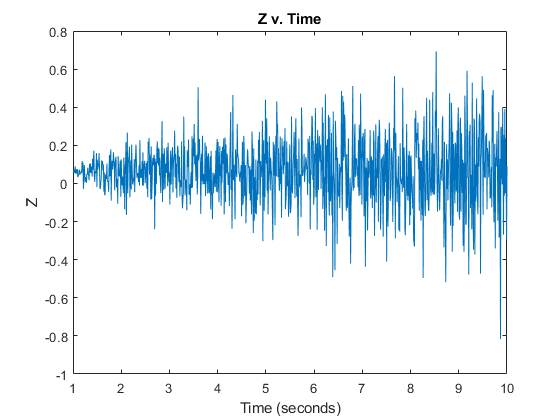

figure
plot(linspace(1,10,1000),LHW1data.q9.z)
xlabel('Time (seconds)')
ylabel('Z')
title('Z v. Time')

### Clearly the variance is growing with time...

### MLE will still correspond to the mean value of Z

bMLE = mean(LHW1data.q9.z);

### LSE

### 
$$\hat b_{LSE}=argmin_b((Z-Hb)^T(Z-Hb))$$


### 
$$\hat b_{LSE}=(H^TH)^{-1}H^TZ$$


N9 = LHW1data.q9.N;
H = ones(N9,1); %H is just a vecotr of ones since z(i)=b+w(i)
bLSE = inv(H'*H)*H'*LHW1data.q9.z;

### BLUE

### 
$$\hat b_{BLUE}=argmin_b(A^TZ)$$


### 
$$\hat b_{BLUE}=(H^TC^{-1}H)^{-1}C^{-1}HZ$$


### 
$$C = \pmatrix {\sigma^2t_1 & 0 & ... & 0 \cr ... & ... &...&...\cr 0 &...& 0& \sigma^2t_n}$$


C = eye(N9);
t=linspace(1,1000,1000);
sigma9 = 0.075;
cvar9 = sigma9.*t;
C = C.*cvar9;
bBLUE = inv(H'*inv(C)*H)*inv(C)*H;
bBLUE = bBLUE'*LHW1data.q9.z;
fprintf('The MLE of the bias is %f, the LSE of the bias is %f, the BLUE of the bias is %f, and the true bias is %f',bMLE,bLSE,bBLUE,LHW1data.q9.b)

The MLE of the bias is 0.065906, the LSE of the bias is 0.065906, the BLUE of the bias is 0.062700, and the true bias is 0.062072

### MLE = 0.065906

### LSE = 0.065906

### BLUE = 0.062700

### TRUE BIAS = 0.062072

### MLE and LSE both represent the mean value of the measurements and both end up overpredicting the bias. BLUE is much closer to the true bias overpredicting by only 6.3E-4 units. Does better since it takes into account the linear increase in the variance over time.